# GLalpha

Plot transfer function (GAF) between angle of incidence and lift using unsteady thin aerofoil theory. Full expression is

Results in this script use the aerodynamic coefficients of a flat plate, which depend on $\nu_{\textrm{ea}} =\frac{x_{\textrm{ea}} -\frac{c}{2}}{\frac{c}{2}}$, with $x_{\textrm{ea}}$ the coordinate of the axis of rotation from the leading edge.

Dependencies:

**    theodorsen.m: **Analytical expression for Theodorsen's lift deficiency function.

Written by:

    Rafael Palacios (r.palacios@imperial.ac.uk)

Latest update:

     April 2024

## Define the transfer function (GAF) between AoA and lift coef.

Eq. (3.54) in book, splitting between circulatory and non-circulatory terms. Circulatory terms are further split between quasi-steady and (unsteady) wake effects.

GLa_qs=@(xx,nu) 2*pi*(1+1i*xx*(1/2-nu));
GLa_c=@(xx,nu) theodorsen(xx).*GLa_qs(xx,nu);
GLa_nc=@(xx,nu) pi*(1i*xx+nu*xx.^2);
GLa =@(xx,nu) GLa_c(xx,nu)+GLa_nc(xx,nu);

## GAF as a function of the rotation axis location

Parameter is $\nu_{\textrm{ea}} =\frac{x_{\textrm{ea}} -\frac{c}{2}}{\frac{c}{2}}$, with $x_{\textrm{ea}}$ the coordinate of the axis of rotation from leading edge. 

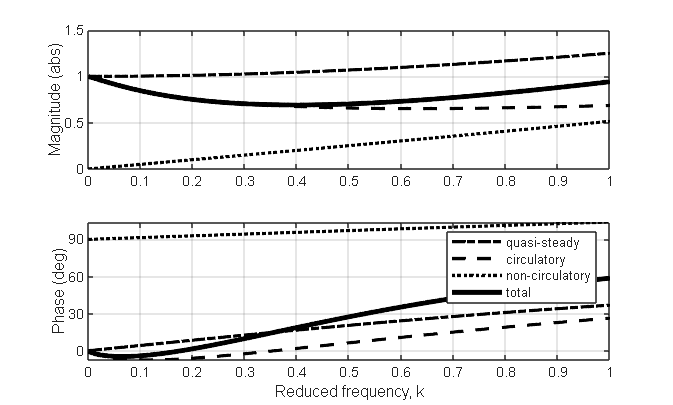

figure, k=0.001:0.001:1; 
nu_ea=-0.25;
  subplot(2,1,1)
   plot(k,abs(GLa_qs(k,nu_ea)/2/pi),'k-.', 'LineWidth',2), hold on
   plot(k,abs(GLa_c(k,nu_ea)/2/pi),'k--', 'LineWidth',2), hold on
   plot(k,abs(GLa_nc(k,nu_ea)/2/pi),'k:', 'LineWidth',2)
   plot(k,abs(GLa(k,nu_ea)/2/pi),'k-', 'LineWidth',3)
  subplot(2,1,2)
   plot(k,angle(GLa_qs(k,nu_ea))*180/pi,'k-.', 'LineWidth',2), hold on
   plot(k,angle(GLa_c(k,nu_ea))*180/pi,'k--', 'LineWidth',2), hold on
   plot(k,angle(GLa_nc(k,nu_ea))*180/pi,'k:', 'LineWidth',2)
   plot(k,angle(GLa(k,nu_ea))*180/pi,'k-', 'LineWidth',3)
% Write legends.
subplot(2,1,1)
    ylabel('Magnitude (abs)'), grid on
subplot(2,1,2)
    xlabel('Reduced frequency, k'), grid on
    ylabel('Phase (deg)')
    yticks([0 30 60 90])
    legend('quasi-steady','circulatory','non-circulatory','total')

Comments:

- At low reduced frequencies (k<0.08), non-circulatory terms (apparent mass) is neglible

- At moderate frequencies (0.08<k<0.3) non-circulatory terms has a minimum effect in amplitude, but do change the phase.

- Both observations are valid for any value of $\nu_{\textrm{ea}}$.

We can also plot GAFs for pitch axis moving from the midpoint ($\nu_{\textrm{ea}}$=0, black) to the L.E. ($\nu_{\textrm{ea}} =-1$, grey).

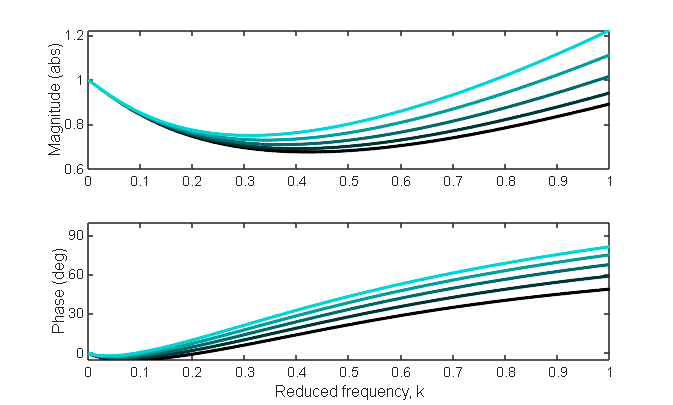

figure 
k=0:0.001:1;
for nu_ea=0:-0.25:-1;
  subplot(2,1,1)
   plot(k,abs(GLa(k,nu_ea)/2/pi),'-','Color',[0 1 1]*abs(nu_ea/1.2), 'LineWidth',2), hold on
  subplot(2,1,2)
   plot(k,angle(GLa(k,nu_ea))*180/pi,'-','Color',[0 1 1]*abs(nu_ea/1.2), 'LineWidth',2), hold on
end
% Write legends.
subplot(2,1,1)
    ylabel('Magnitude (abs)')
subplot(2,1,2)
    xlabel('Reduced frequency, k')
    ylabel('Phase (deg)')
    yticks([0 30 60 90])

## Plot time-history of alpha vs. CL for harmonic motions.

Parameters are the axis of of rotation ($$\nu_{ea}$$) and the reduced frequency of the oscillations.

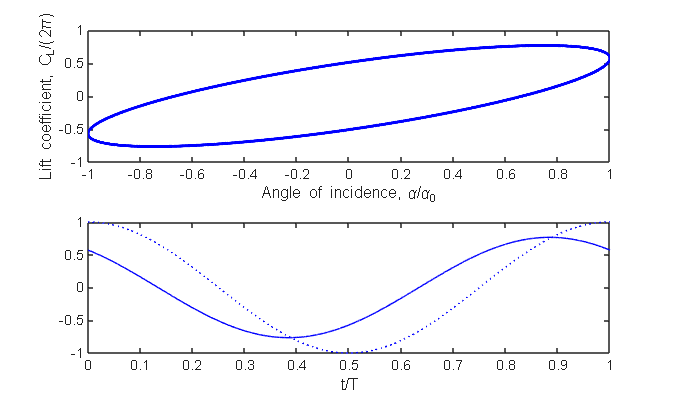

figure
nu_ea=-0.5;
k=0.6;

theta=0:0.001:2*pi;  % Full cycle in k*s.
alpha=cos(theta);
subplot(2,1,1)
    plot(alpha,real(GLa(k,nu_ea)*exp(1i*theta))/2/pi,'b','LineWidth',2), hold on
    xlabel('Angle of incidence, \alpha/\alpha_0')
    ylabel('Lift coefficient, C_L/(2\pi)')
    axis([-1 1 -1 1])
subplot(2,1,2)
    plot(theta/2/pi,alpha,'b:'), hold on
    plot(theta/2/pi,real(GLa(k,nu_ea)*exp(1i*theta))/2/pi,'b-')
    xlabel ('t/T')

Comparison for three values of the reduced frequency.

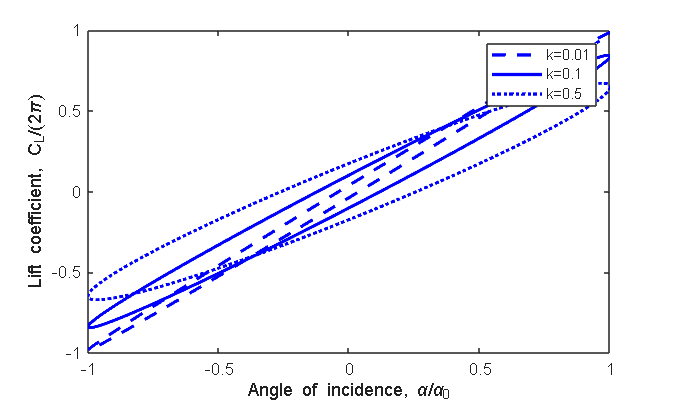

figure
nu_ea= 0.25;
theta=0:0.001:2*pi;  % Full cycle in k*s.
alpha=cos(theta);

k=0.01; plot(alpha,real(GLa(k,nu_ea)*exp(1i*theta))/2/pi,'b--','LineWidth',2), hold on
k=0.1;  plot(alpha,real(GLa(k,nu_ea)*exp(1i*theta))/2/pi,'b-','LineWidth',2), hold on
k=0.5;  plot(alpha,real(GLa(k,nu_ea)*exp(1i*theta))/2/pi,'b:','LineWidth',2)

legend('k=0.01','k=0.1','k=0.5')
xlabel('Angle of incidence, \alpha/\alpha_0')
ylabel('Lift coefficient, C_L/(2\pi)')